% State Space Modelling for a Rocket
% Felix Zauner
% 22.02.2026

% Define Parameters
clear; clc;

params = struct();
params.g   = 9.81;
params.rho = 1.225;

params.S = 0.01;
params.d = 0.10;

params.m  = 1.2;
params.Ix = 0.02;
params.Iy = 0.02;
params.Iz = 0.005;

% Aeromodell-Parameter (Startwerte)
params.CA0       = 0.30;
params.CA_kalpha = 1.0;
params.CA_kbeta  = 1.0;
params.CN_alpha  = 10.0;

% Moment-Parameter (Startwerte) – setz irgendwas sinnvolles
params.Cl_delta = 0.5;
params.Clp      = -10;
params.Cm_alpha = -2;
params.Cm_delta = -1;
params.Cmq      = -40;
params.Cn_beta  = 2;
params.Cn_delta = 1;
params.Cnr      = -30;

params.x_cm  = 0.6;
params.x_ref = 0.5;

% Nonlinear Function for a Rocket
function xdot = rocket_f(~, x, u_in, P)
% x = [u v w p q r phi theta psi]'
% u_in = [delta_eta delta_zeta delta_r T]' 

% --- unpack state ---
ub    = x(1);  vb = x(2);  wb = x(3);       
p     = x(4);  q  = x(5);  r  = x(6);
phi   = x(7);  theta = x(8); psi = x(9);

% --- unpack inputs ---
delta_eta  = u_in(1);
delta_zeta = u_in(2);
delta_r    = u_in(3);
T          = u_in(4);

m  = P.m;
Ix = P.Ix; Iy = P.Iy; Iz = P.Iz;

% --- derived quantities ---
VM = sqrt(ub^2 + vb^2 + wb^2) + 1e-9;  % avoid div0

alpha = atan2(wb, ub);                % small angles ok
beta  = asin(max(min(vb/VM, 1), -1)); % clamp for numeric safety

rho = P.rho; 
% --- aerodynamic coefficients (simple small-angle model) ---
alpha_t = atan2(sqrt(vb^2 + wb^2),ub);

% Reasonable starter values (tune later)
CA0      = P.CA0;       
k_alpha  = P.CA_kalpha; 
k_beta   = P.CA_kbeta;  
CN_alpha = P.CN_alpha;  

CA = CA0 + k_alpha*alpha^2 + k_beta*beta^2;
CN = CN_alpha * alpha_t;

% Split CN into body y/z based on lateral velocity components
vw = sqrt(vb^2 + wb^2);
if vw < 1e-6
    CNy = 0;
    CNz = 0;
else
    CNy = CN * (-vb)/vw;
    CNz = CN * ( wb)/vw;
end

FAxb = -0.5*rho*VM^2*CA*P.S;
FAyb =  0.5*rho*VM^2*CNy*P.S;
FAzb =  0.5*rho*VM^2*CNz*P.S;

% --- thrust in body ---
FPxb = T;  FPyb = 0;  FPzb = 0;

% --- gravity in body: Fg_b = R_nb' * [0;0;mg] in NED ---
Fg_b = gravity_body(phi, theta, psi, m, P.g); 
Fgxb = Fg_b(1); Fgyb = Fg_b(2); Fgzb = Fg_b(3);

% --- total forces ---
Fx = FAxb + FPxb + Fgxb;
Fy = FAyb + FPyb + Fgyb;
Fz = FAzb + FPzb + Fgzb;

% --- moment coefficients  ---
Cl = P.Cl_delta*delta_r + (P.d/(2*VM))*(P.Clp*p);

Cm_ref = P.Cm_alpha*alpha + P.Cm_delta*delta_eta;
Cn_ref = P.Cn_beta*beta  + P.Cn_delta*delta_zeta;

Cm = Cm_ref - CNz*(P.x_cm - P.x_ref)/P.d + (P.d/(2*VM))*(P.Cmq)*q; % ggf + C_malphadot-Teil später
Cn = Cn_ref + CNy*(P.x_cm - P.x_ref)/P.d + (P.d/(2*VM))*(P.Cnr)*r;

LA = 0.5*rho*VM^2*P.S*P.d*Cl;
MA = 0.5*rho*VM^2*P.S*P.d*Cm;
NA = 0.5*rho*VM^2*P.S*P.d*Cn;

% Propulsion moments 
Lp = 0; Mp = 0; Np = 0;

% --- translational dynamics in body ---
udot = Fx/m - (q*wb - r*vb);
vdot = Fy/m - (r*ub - p*wb);
wdot = Fz/m - (p*vb - q*ub);

% --- rotational dynamics ---
pdot = (LA + Lp - q*r*(Iz - Iy))/Ix;
qdot = (MA + Mp - r*p*(Ix - Iz))/Iy;
rdot = (NA + Np - p*q*(Iy - Ix))/Iz;

% --- Euler kinematics ---
phidot   = p + (q*sin(phi) + r*cos(phi))*tan(theta);
thetadot = q*cos(phi) - r*sin(phi);
psidot   = (q*sin(phi) + r*cos(phi))/cos(theta);

xdot = [udot; vdot; wdot; pdot; qdot; rdot; phidot; thetadot; psidot];
end

% Gravity
function Fg_b = gravity_body(phi, theta, psi, m, g)
% NED: gravity in nav frame is [0;0; +m*g] (Down positive)
Fg_n = [m*g; 0;0];

% Rotation matrix R_b^n (ZYX) and R_n^b = (R_b^n)'
R_b_n = eul2Rbn(phi, theta, psi);  % body->nav
R_n_b = R_b_n';

Fg_b = R_n_b * Fg_n;
end

function R_b_n = eul2Rbn(phi, theta, psi)
cphi = cos(phi); sphi = sin(phi);
cth  = cos(theta); sth = sin(theta);
cps  = cos(psi); sps  = sin(psi);

% ZYX: body->nav (matches common aerospace convention)
R_b_n = [ cth*cps,  sphi*sth*cps - cphi*sps,  cphi*sth*cps + sphi*sps;
          cth*sps,  sphi*sth*sps + cphi*cps,  cphi*sth*sps - sphi*cps;
          -sth,     sphi*cth,              cphi*cth ];
end

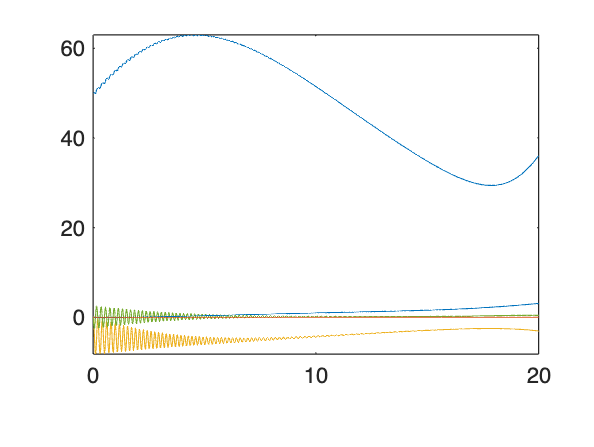

x0 = zeros(9,1);
x0(1) = 50; % u initial speed

u_in = [0; 0; 0; 10]; % delta_eta, delta_zeta, delta_r, T

tspan = [0 20];
[t,x] = ode45(@(t,x) rocket_f(t,x,u_in,params), tspan, x0);
plot(t,x);